## **HCP Lockbox Sample - Region-Specific Coupling All Conditions - 4 Measures **

Computation of region-specific SC-FC coupling maps (measure that is able to explain the hightest variance in FC across all participants most frequently) and creation of correlation matrix depicting the similarity between vectos of regional SC-FC coupling pattern. 

Before running this script: 

- run all scripts in HCP Data Prep

**1. Create a group-average map depicting the regional SC-FC coupling pattern for each condition **

1.1. Create a cell that contains for each subject a vector og 8 predictors for each node

for i = 1:232
    x = final_r_all_HCP_rest_232{i,2};% change here to switch between the 8 conditions(rest/task)
    for j = 1:358
    Node_all_baseline_best_measures_HCP_r2{i,j} = x(j,:);
    end
end


1.2. Create a cell containing information about all subjects and coupling measures per node

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 232*8 matrix for each node)

n = size(Node_all_baseline_best_measures_HCP_r2,2);
All_Nodes_complete_baseline_best_measures_HCP_r2 = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_best_measures_HCP_r2{j} = vertcat(Node_all_baseline_best_measures_HCP_r2{:,j});
end 

1.3. Only keep 4 measures: path length (1), communicability (2), cosine distance (3) & search information (4) 

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_baseline_best_measures_HCP_r2{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_baseline_best_measures_HCP_r2_4_measures{1,i} = four_measures_per_node;
end

1.4. Collect the highest coupling value and the respective coupling measure per node 

Max_values_individuals_HCP = zeros(232,358);
Max_indices_individuals_HCP = zeros(232,358);

for i = 1:358
    node_values = All_Nodes_complete_baseline_best_measures_HCP_r2_4_measures{1,i};

    for p = 1:232
        individual_values = node_values(p,:);
        max_r2 = max(individual_values);
        idx_max = find(individual_values == max_r2); 
        
        if size(idx_max,2) == 2
            idx_max = idx_max(randi(length(idx_max),1)) %if two values have the exact same magnitude that this is randomly picking one out of the two 
        end
        
        Max_values_individuals_HCP(p,i) = max_r2;
        Max_indices_individuals_HCP(p,i) = idx_max;

    end
end

1.5. Find out mode for each node (group-based mask) 

Mode_for_all_nodes = zeros(1,358);

for i = 1:358
    all_selected_measures_per_node = Max_indices_individuals_HCP(:,i);
    [mode_node,frequency_mode] = mode(all_selected_measures_per_node);
    Mode_for_all_nodes(1,i) = mode_node;
end

1.6. Extract the values per node from measure that was selected with the highest frequency (mode) and average across all participants 

Mean_values_across_all_nodes = zeros(1,358);
Stdev_values_across_all_nodes = zeros(1,358);

for i = 1:358
    
node_values = All_Nodes_complete_baseline_best_measures_HCP_r2_4_measures{1,i};
measure_highest_occurence = Mode_for_all_nodes(i);
node_values_measure_highest_occurence = node_values(:,measure_highest_occurence);

mean_per_node = mean(node_values_measure_highest_occurence);
stdev_per_node = std(node_values_measure_highest_occurence); 

Mean_values_across_all_nodes(1,i) = mean_per_node;
Stdev_values_across_all_nodes(1,i) = stdev_per_node;

end

**2. Create the brain maps (mean)**

2.1. Convert cell to mat

Mean_values_across_all_nodes_mat = Mean_values_across_all_nodes % rename the variable here depending on condition that input data is coming from (important for the correlation matrix later)

Mean_values_across_all_nodes_mat =     0.1582    0.1059    0.1760    0.2227    0.2319    0.2595    0.3105    0.2764    0.2542    0.0418    0.0557    0.0754    0.2323    0.1379    0.0874    0.2516    0.1188    0.1570    0.2946    0.2959    0.2857    0.2589    0.1240    0.1685    0.0570    0.0715    0.0485    0.0723    0.0906    0.0898    0.1076    0.0605    0.0931    0.1125    0.1140    0.2149    0.1024    0.0462    0.2358    0.2454    0.1405    0.1694    0.1349    0.0964    0.0965    0.1104    0.1532    0.0307    0.0692    0.1165


min(Mean_values_across_all_nodes_mat)

ans = 0.0106

max(Mean_values_across_all_nodes_mat)

ans = 0.3306

2.2. Insert a 0 at node 120 & 300

a = Mean_values_across_all_nodes_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Mean_values_across_all_nodes_mat_360 = a

Mean_values_across_all_nodes_mat_360 =     0.1582    0.1059    0.1760    0.2227    0.2319    0.2595    0.3105    0.2764    0.2542    0.0418    0.0557    0.0754    0.2323    0.1379    0.0874    0.2516    0.1188    0.1570    0.2946    0.2959    0.2857    0.2589    0.1240    0.1685    0.0570    0.0715    0.0485    0.0723    0.0906    0.0898    0.1076    0.0605    0.0931    0.1125    0.1140    0.2149    0.1024    0.0462    0.2358    0.2454    0.1405    0.1694    0.1349    0.0964    0.0965    0.1104    0.1532    0.0307    0.0692    0.1165


Mean_values_across_all_nodes_mat_360(120) = NaN;
Mean_values_across_all_nodes_mat_360(300)= NaN;

2.3. Plot

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = Mean_values_across_all_nodes_mat_360

dataVec =     0.1582    0.1059    0.1760    0.2227    0.2319    0.2595    0.3105    0.2764    0.2542    0.0418    0.0557    0.0754    0.2323    0.1379    0.0874    0.2516    0.1188    0.1570    0.2946    0.2959    0.2857    0.2589    0.1240    0.1685    0.0570    0.0715    0.0485    0.0723    0.0906    0.0898    0.1076    0.0605    0.0931    0.1125    0.1140    0.2149    0.1024    0.0462    0.2358    0.2454    0.1405    0.1694    0.1349    0.0964    0.0965    0.1104    0.1532    0.0307    0.0692    0.1165


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [0 0.3500]
    viewcMap: 1
     viewStr: 'all'


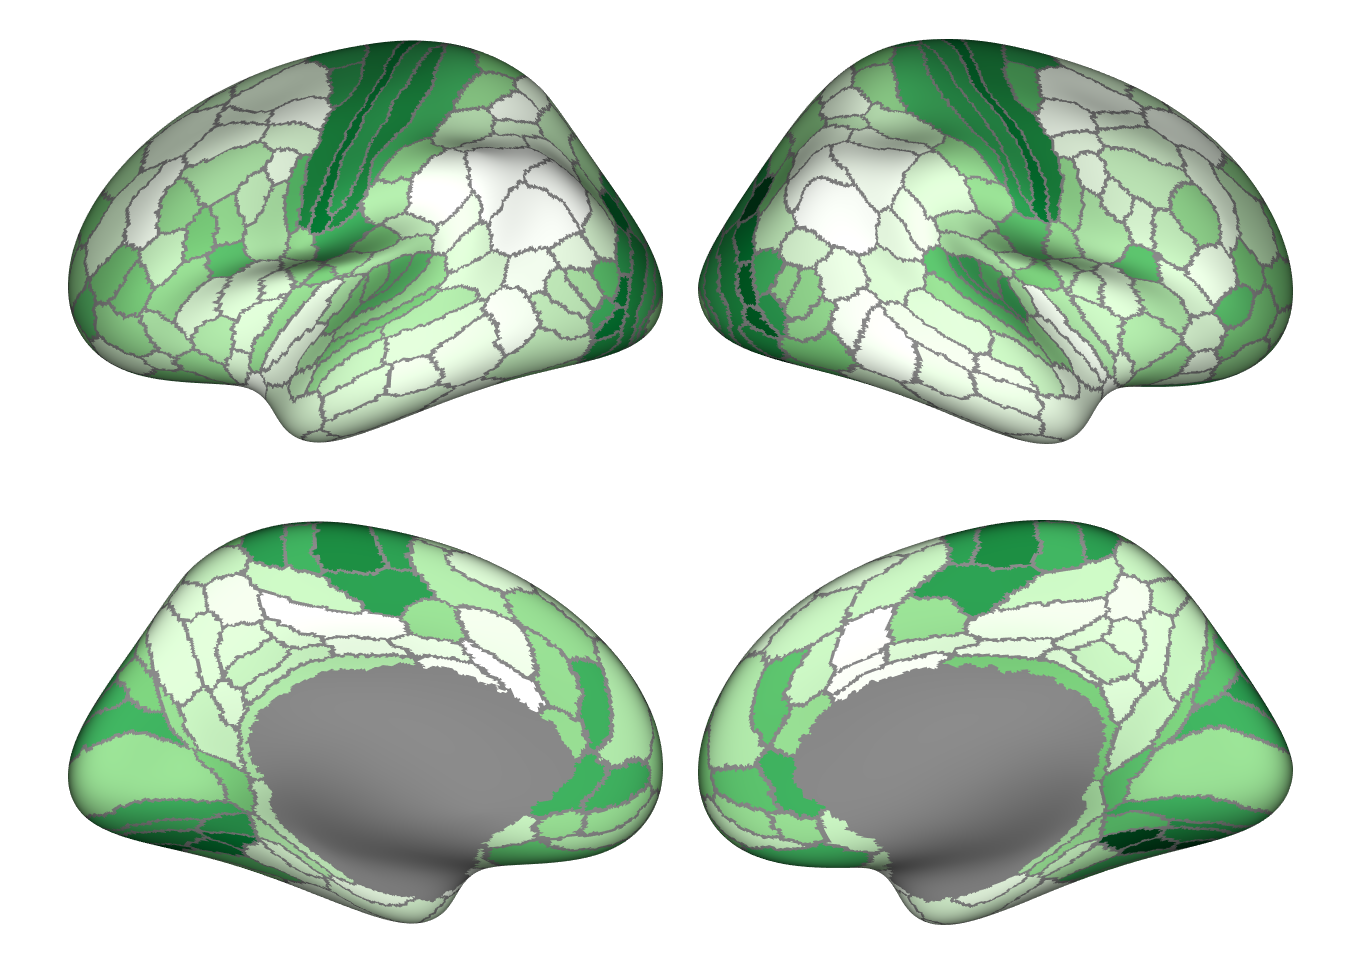

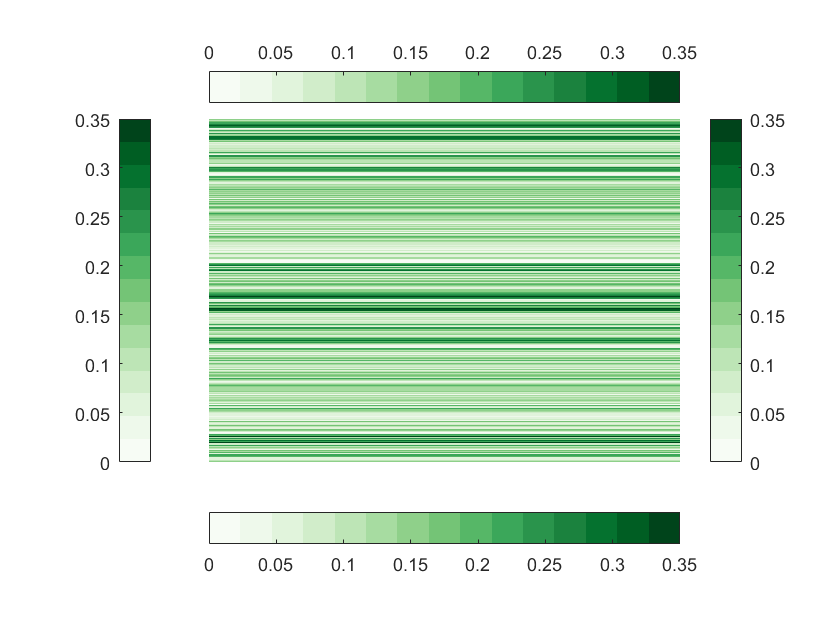

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec,'cMap',brewermap(15,'Greens'),...
    'viewcMap',1, 'valRange', ([0 0.35]))

**3. Create the brain maps (Stdev)**

3.1. Convert cell to mat

Stdev_values_across_all_nodes_mat = Stdev_values_across_all_nodes % rename the variable here depending on condition that input data is coming from (important for the correlation matrix later)

Stdev_values_across_all_nodes_mat =     0.0635    0.0585    0.0673    0.0540    0.0507    0.0468    0.0672    0.0644    0.0575    0.0366    0.0569    0.0576    0.0530    0.0493    0.0458    0.0750    0.0441    0.0449    0.0785    0.0738    0.0746    0.0732    0.0603    0.0565    0.0366    0.0523    0.0402    0.0476    0.0473    0.0297    0.0411    0.0362    0.0287    0.0310    0.0315    0.0812    0.0572    0.0356    0.0649    0.0701    0.0624    0.0516    0.0704    0.0433    0.0398    0.0434    0.0575    0.0285    0.0481    0.0385


min(Stdev_values_across_all_nodes_mat)

ans = 0.0114

max(Stdev_values_across_all_nodes_mat)

ans = 0.0978

3.2. Insert a 0 at node 120 & 300

a = Stdev_values_across_all_nodes_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Stdev_values_across_all_nodes_mat_360 = a

Stdev_values_across_all_nodes_mat_360 =     0.0635    0.0585    0.0673    0.0540    0.0507    0.0468    0.0672    0.0644    0.0575    0.0366    0.0569    0.0576    0.0530    0.0493    0.0458    0.0750    0.0441    0.0449    0.0785    0.0738    0.0746    0.0732    0.0603    0.0565    0.0366    0.0523    0.0402    0.0476    0.0473    0.0297    0.0411    0.0362    0.0287    0.0310    0.0315    0.0812    0.0572    0.0356    0.0649    0.0701    0.0624    0.0516    0.0704    0.0433    0.0398    0.0434    0.0575    0.0285    0.0481    0.0385


Stdev_values_across_all_nodes_mat_360(120) = NaN;
Stdev_values_across_all_nodes_mat_360(300)= NaN;

3.3. Plot

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = Stdev_values_across_all_nodes_mat_360

dataVec =     0.0635    0.0585    0.0673    0.0540    0.0507    0.0468    0.0672    0.0644    0.0575    0.0366    0.0569    0.0576    0.0530    0.0493    0.0458    0.0750    0.0441    0.0449    0.0785    0.0738    0.0746    0.0732    0.0603    0.0565    0.0366    0.0523    0.0402    0.0476    0.0473    0.0297    0.0411    0.0362    0.0287    0.0310    0.0315    0.0812    0.0572    0.0356    0.0649    0.0701    0.0624    0.0516    0.0704    0.0433    0.0398    0.0434    0.0575    0.0285    0.0481    0.0385


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [0 0.1000]
    viewcMap: 1
     viewStr: 'all'


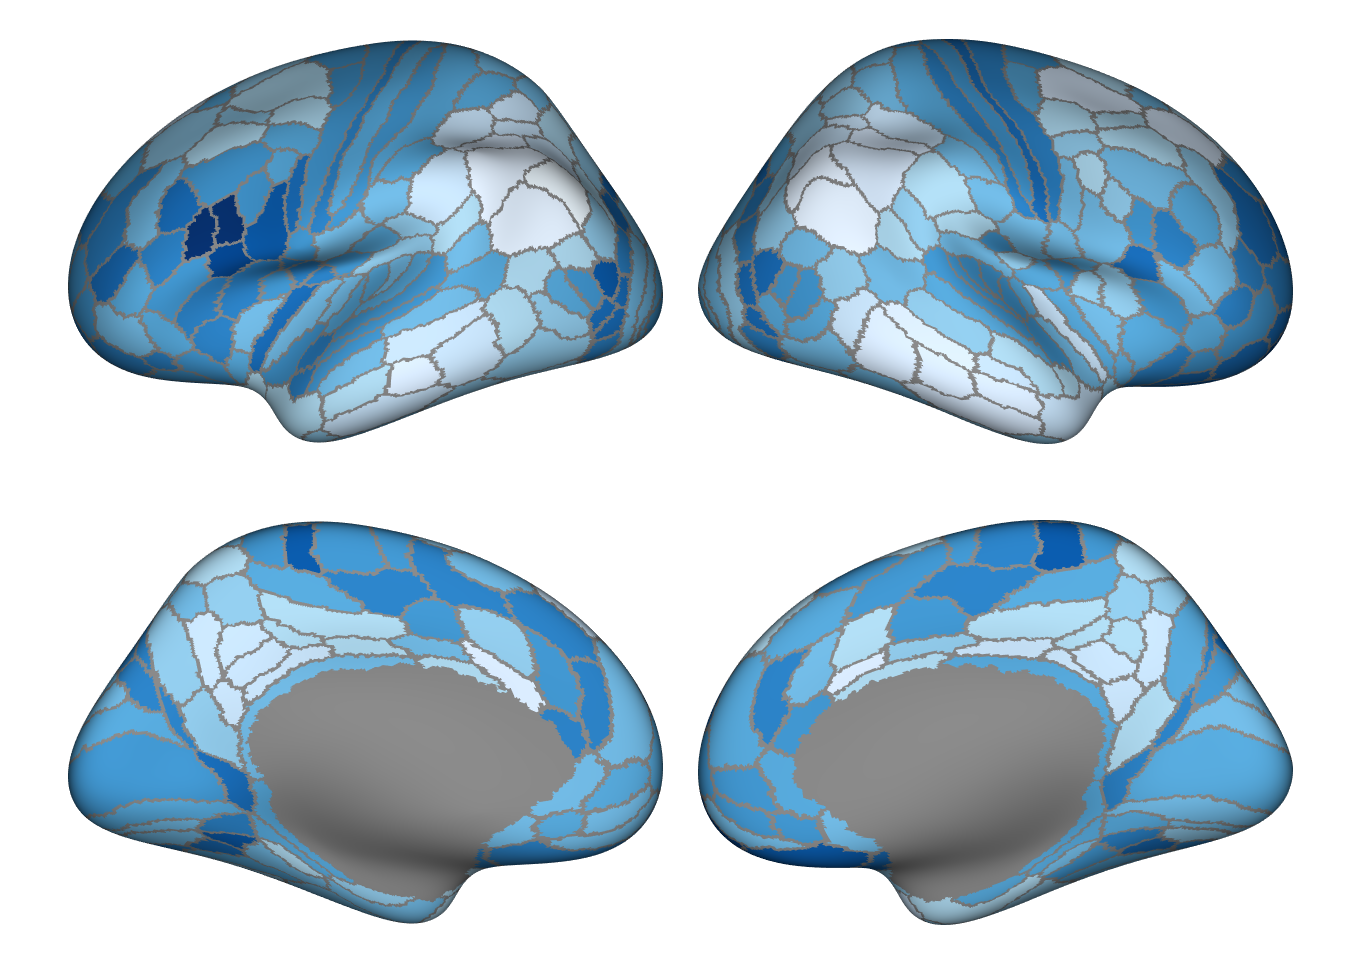

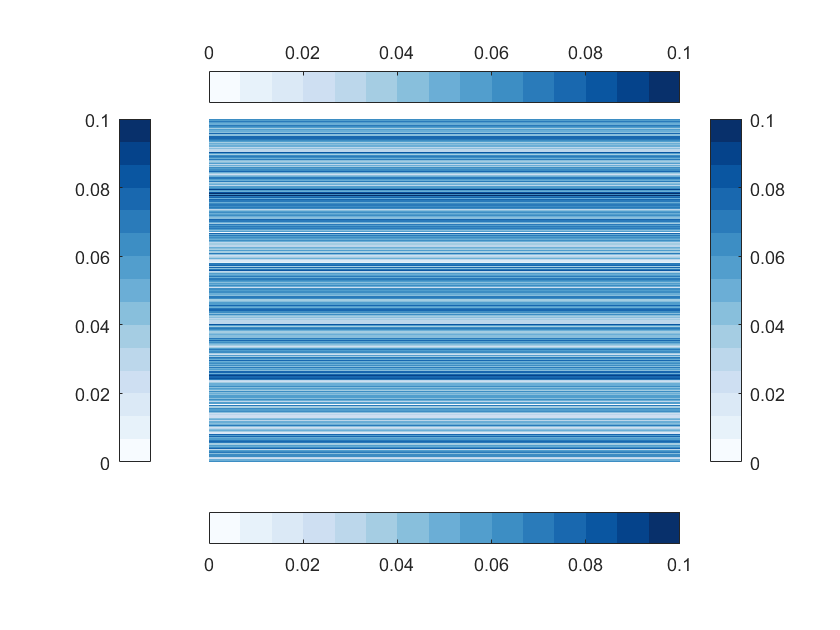

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec,'cMap',brewermap(15,'Blues'),...
    'viewcMap',1, 'valRange', ([0 0.1]))

**4. Creation of correlation matrix depicting the similarity of condition-specific SC-FC coupling patterns **

4.1. Create the correlation matrix

coupling_vectors_all_conditions = [Mean_values_across_all_nodes_rest' Mean_values_across_all_nodes_emotion' Mean_values_across_all_nodes_gambling' Mean_values_across_all_nodes_language' Mean_values_across_all_nodes_motor' Mean_values_across_all_nodes_relational' Mean_values_across_all_nodes_social' Mean_values_across_all_nodes_wm']

Unrecognized function or variable 'Mean_values_across_all_nodes_rest'.

correlation_matrix = corrcoef(coupling_vectors_all_conditions)

4.2. Plot the correlation matrix

imagesc(correlation_matrix)
colorbar
set(gca, 'XTick', 1:8); % center x-axis ticks on bins
set(gca, 'YTick', 1:8); % center y-axis ticks on bins
xticklabels({'rest', 'emotion', 'gambling','language' ,'motor' , 'relational', 'social', 'wm'})
set(gca,'xaxisLocation','top')
yticklabels({'rest', 'emotion', 'gambling','language' ,'motor' , 'relational', 'social', 'wm'})
title('Correlation between condition-specific coupling measures', 'FontSize', 10); % set title
colormap('jet'); % Choose jet or any other color scheme